## Polar Overturning Conceptual Model

#### Live script to run experiments and produce the figures.

#### twnh Aug, Sep '19, Jan–May '20, Sep '20, Oct '23

Must cd to the working directory to run the notebook. The notebook writes pdf figures to the figures directory. Crop them to make publication-ready figures.

Housekeeping:

clear
clear plot_POC_TS_diagram  % Clears persistent variables from this function.
close all
clc
%parpool('MJSProfile1',84) 
if(isempty(gcp))
    %parpool('MJSProfile1',84)
    parpool('local',16) 
end

Exp 1: Northern hemisphere Fram Strait/Barents Sea Opening. This is the canonical case from H21.

model1 = build_POC_model('NH_FSBSO_can') ;

 Solutions for experiment: [Exp.~1 Fram Strait+BSO] with file suffices: [NH_FSBSO_can]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      3.4000          |           35.0000          |            4.7500
 Atlantic Water to shelf:             3.4000          |           35.0000          |   0.1028   0.2689   0.6421
 Polar    Water:                     -1.8675          |           34.3235          |  -1.7039  -1.0863  -0.0000
 Overflow Water:             1.2043   1.4288   1.5674 |  34.9022  34.9549  35.0714 |  -4.7261  -3.6699  -3.0705
 Shelf    Water:            -1.9941  -2.0607  -2.2015 |  36.4907  37.6234  40.0000 |  -0.5902  -0.2291  -0.0747
 Ambient

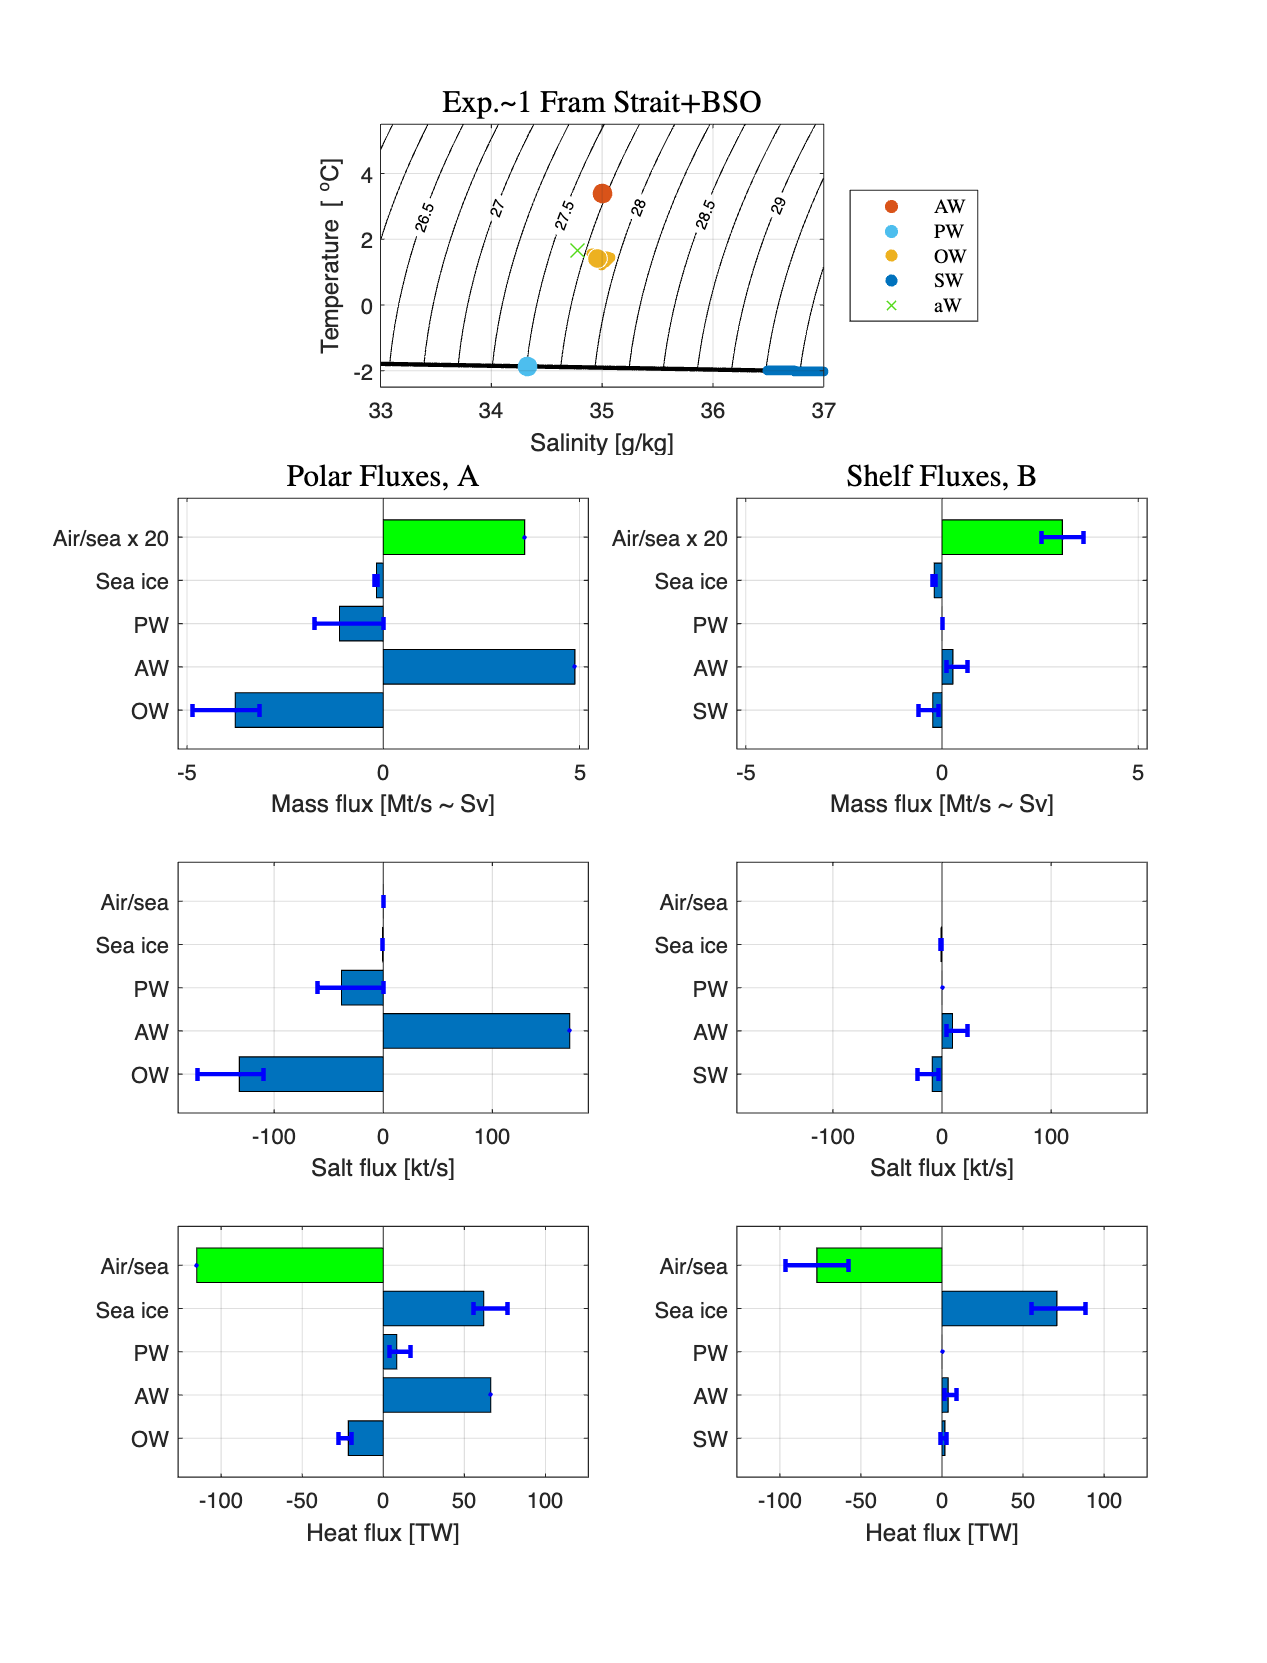

plot_POC_solution(model1)

Exp 1b: Northern hemisphere Fram Strait/Barents Sea Opening with updated parameters from Tsubouchi et al. (2023) in October '23.

model1b = build_POC_model('NH_FSBSO_can_Oct23') ;

 Solutions for experiment: [Exp.~1b Fram Strait+BSO] with file suffices: [NH_FSBSO_can_Oct23]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      3.7261          |           35.0087          |            3.9000
 Atlantic Water to shelf:             3.7261          |           35.0087          |   0.0119   0.0379   1.8023
 Polar    Water:                     -1.8638          |           34.2596          |  -3.6684  -3.6325  -0.0143
 Overflow Water:             0.0617   1.6207   1.8498 |  34.7750  34.8041  34.9049 |  -3.8799  -0.3387  -0.3036
 Shelf    Water:            -1.8952  -1.9293  -2.2015 |  34.7987  35.3843  40.0000 |  -1.7800  -0.0232  -0.0024
 

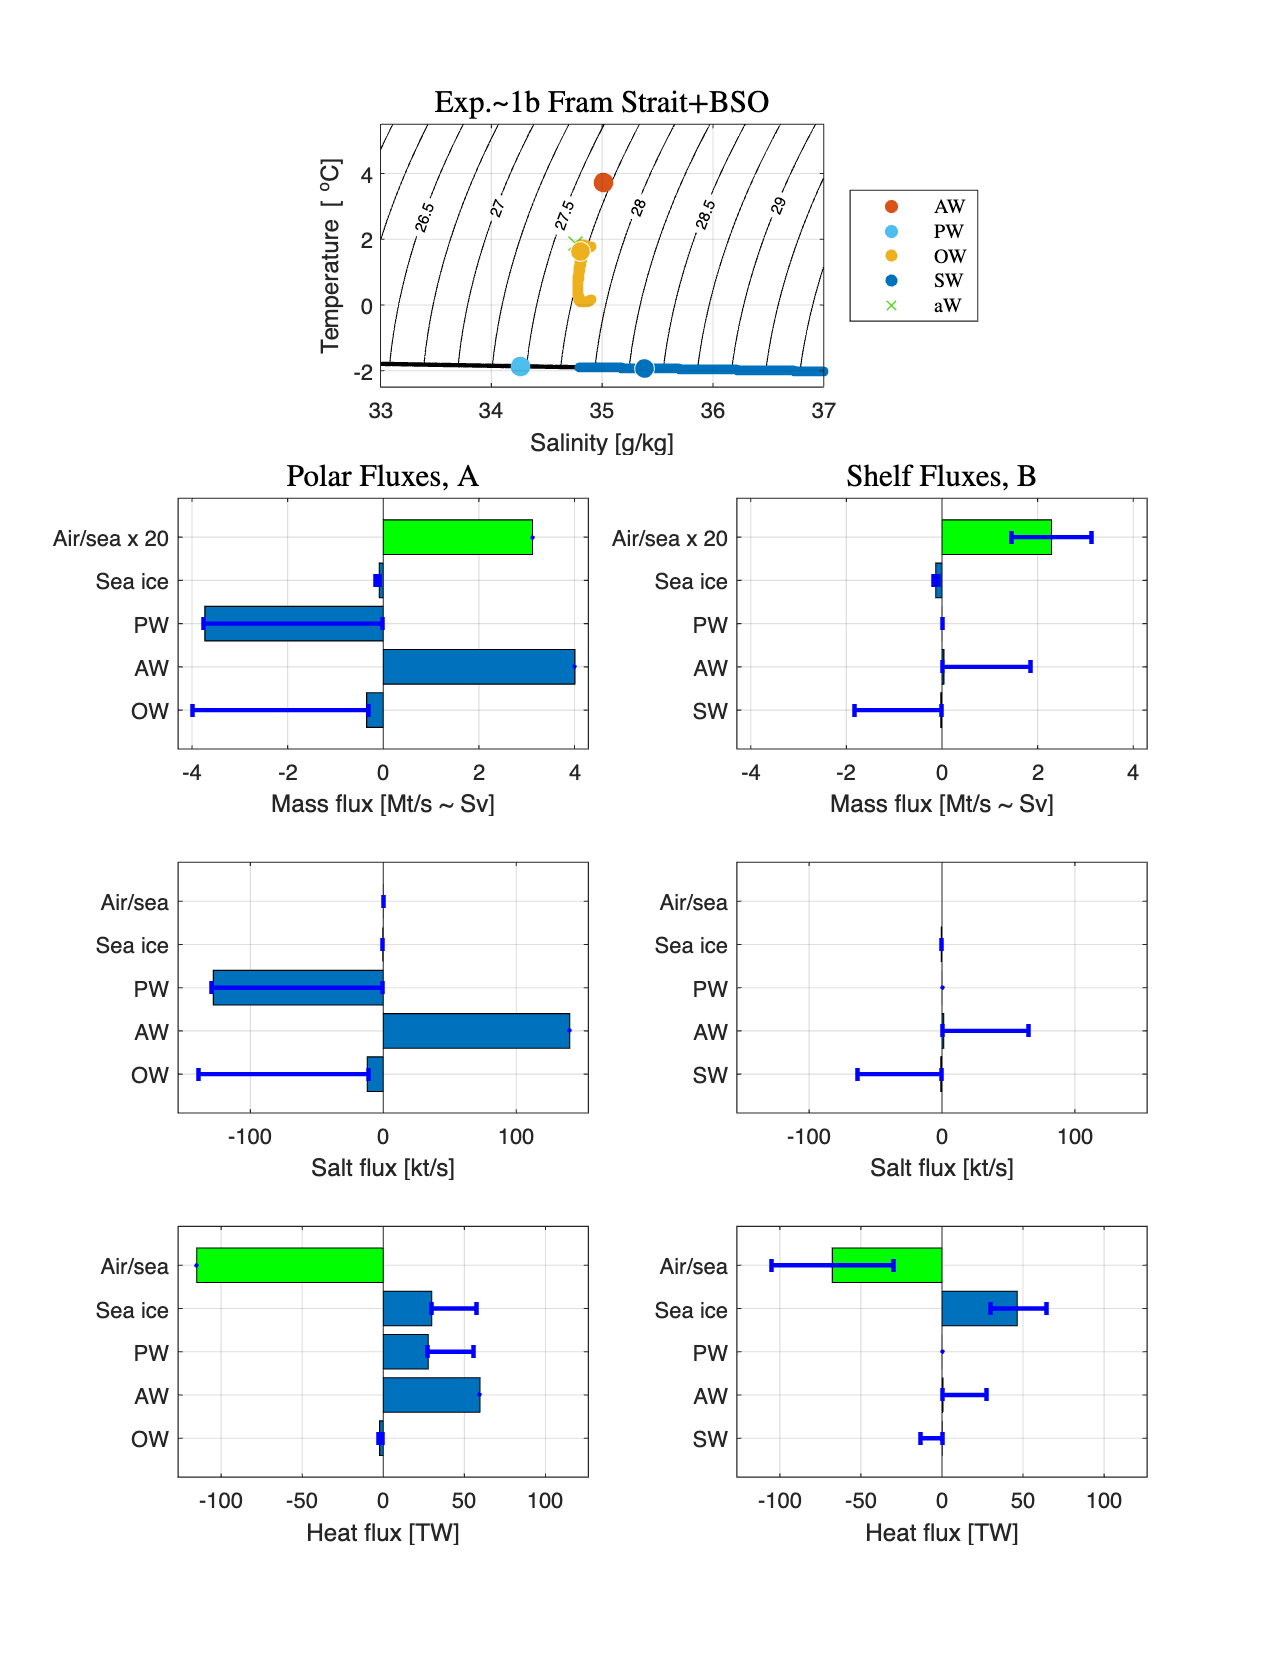

plot_POC_solution(model1b)

Exp 3: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values.

model3 = build_POC_model('NH_FSBSO_range') ;

 Solutions for experiment: [Exp.~3 Fram Strait+BSO various ${\cal Q}$] with file suffices: [NH_FSBSO_range]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   4.7500   4.7500   4.7500
 Atlantic Water to shelf:    3.4000   3.4000   3.4000 |  35.0000  35.0000  35.0000 |   0.0106   1.5566   4.7388
 Polar    Water:            -1.8675  -1.8675  -1.8675 |  34.3235  34.3235  34.3235 |  -4.8302  -1.8771  -0.0000
 Overflow Water:            -1.8966   0.0502   1.6355 |  34.5892  34.8604  35.1110 |  -4.7494  -2.9035  -0.0036
 Shelf    Water:            -1.8828  -1.9594  -2.2015 |  34.5853  35.8984  40.0000 |  -4.7

% plot_POC_solutions1(model3,model1,model1b) ;

Exp 4: Northern hemisphere Fram Strait/Barents Sea Opening with wide range of all parameters.

model4 = build_POC_model('NH_FSBSO_sens') ;

 Solutions for experiment: [Exp.~4 Fram Strait+BSO sensitivity] with file suffices: [NH_FSBSO_sens]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             2.5500   3.5417   4.5333 |  34.3000  35.0000  35.7000 |   3.1667   5.1458   7.1250
 Atlantic Water to shelf:    2.5500   3.5417   4.5333 |  34.3000  35.0000  35.7000 |   0.0000   1.9014   7.1246
 Polar    Water:            -1.9174  -1.8654  -1.8129 |  33.3813  34.2866  35.1791 |  -7.3082  -2.0430  -0.0000
 Overflow Water:            -1.9483   0.0488   2.4289 |  33.7579  34.8469  35.9065 |  -7.1726  -3.4186  -0.0000
 Shelf    Water:            -1.8347  -1.9558  -2.2015 |  33.7579  35.8370  39.9999 |  -7.1559  -1.

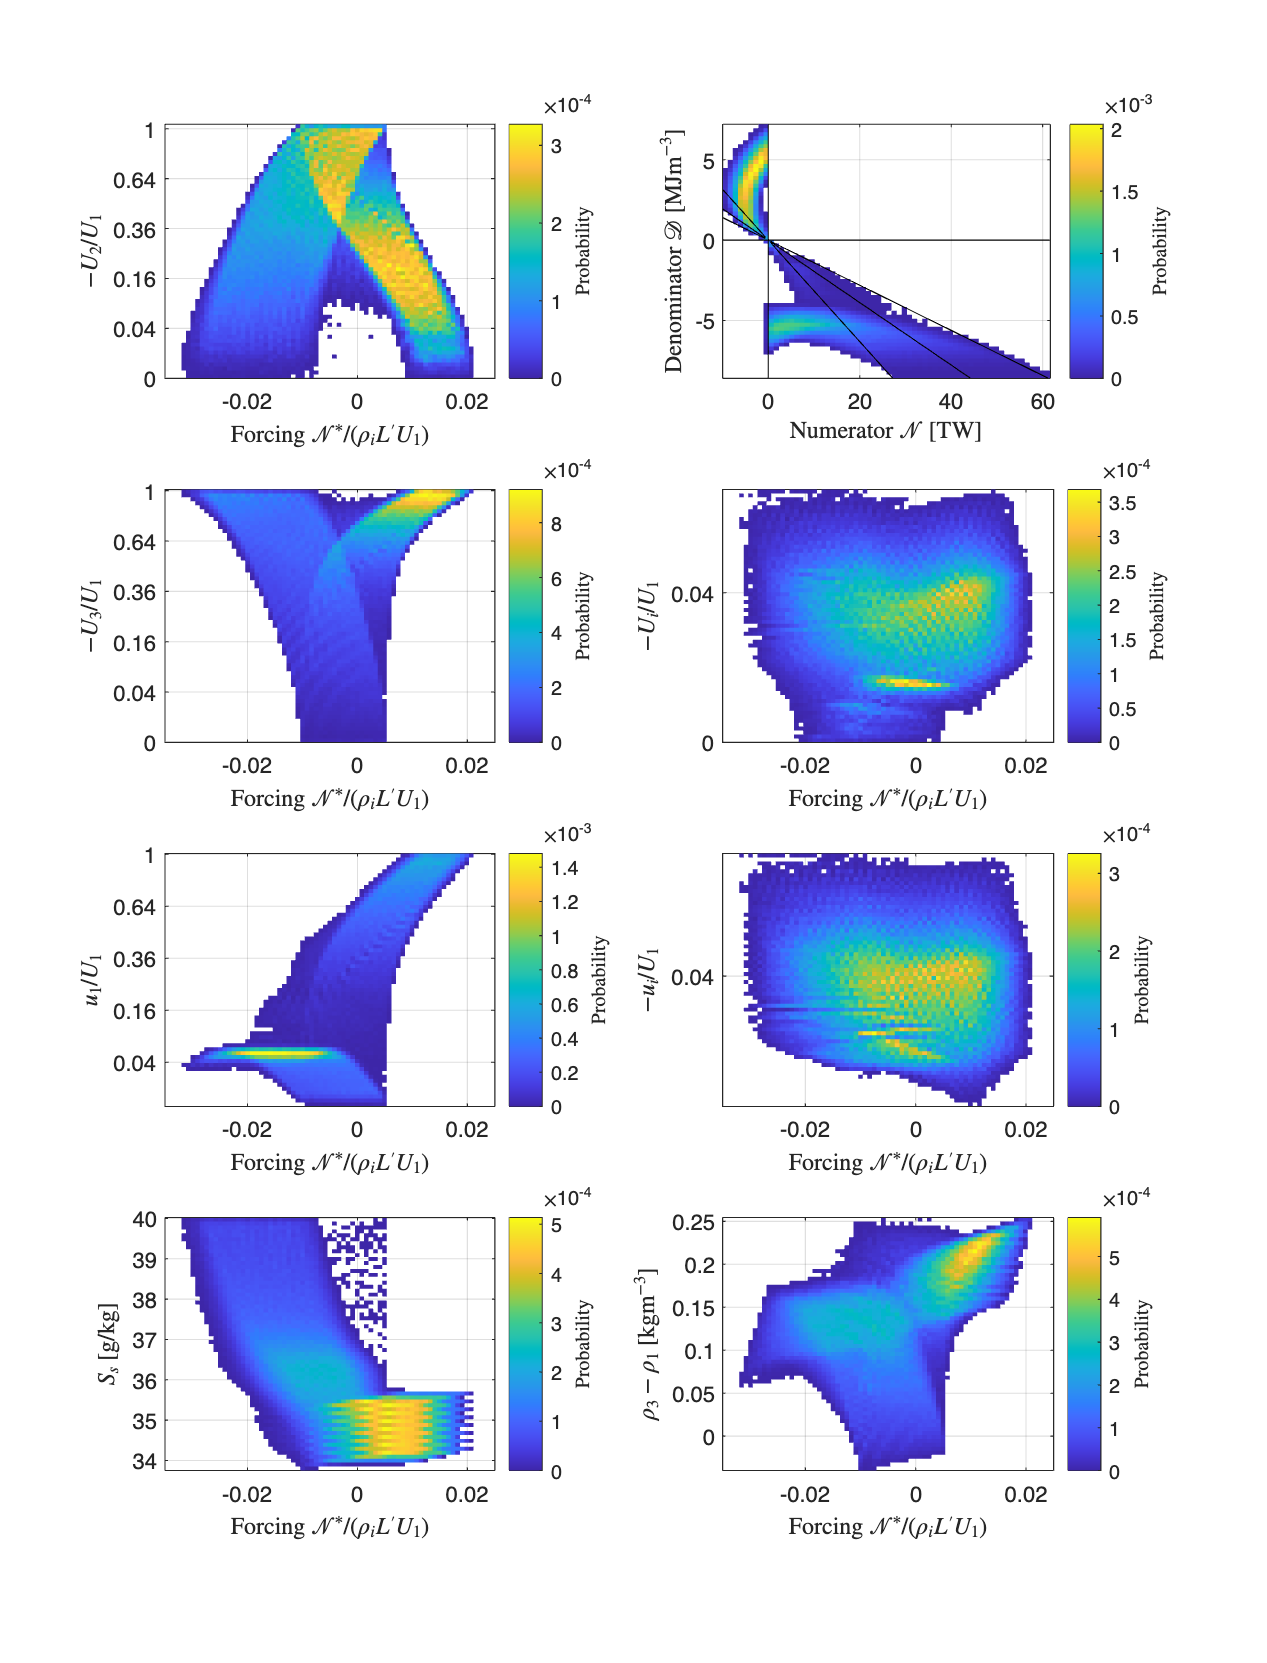

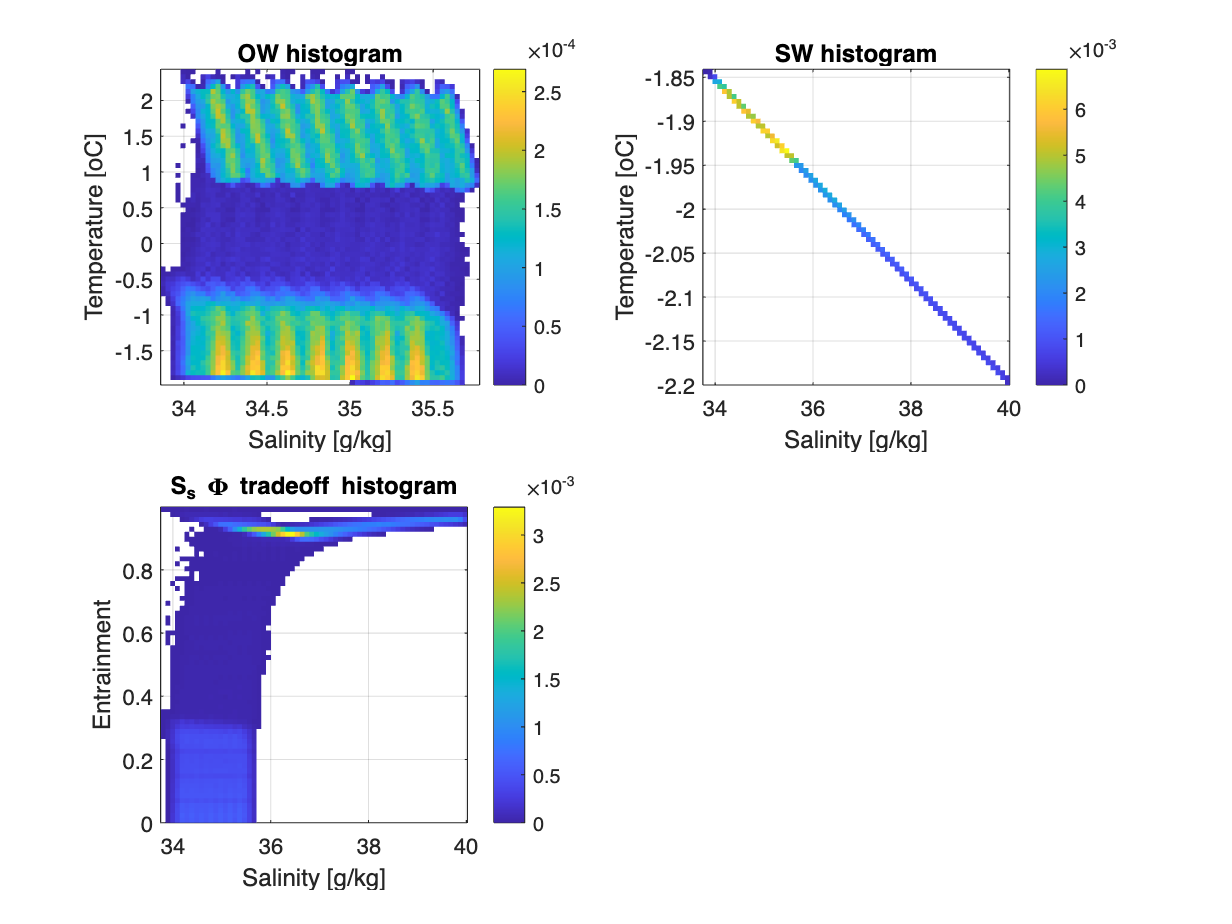

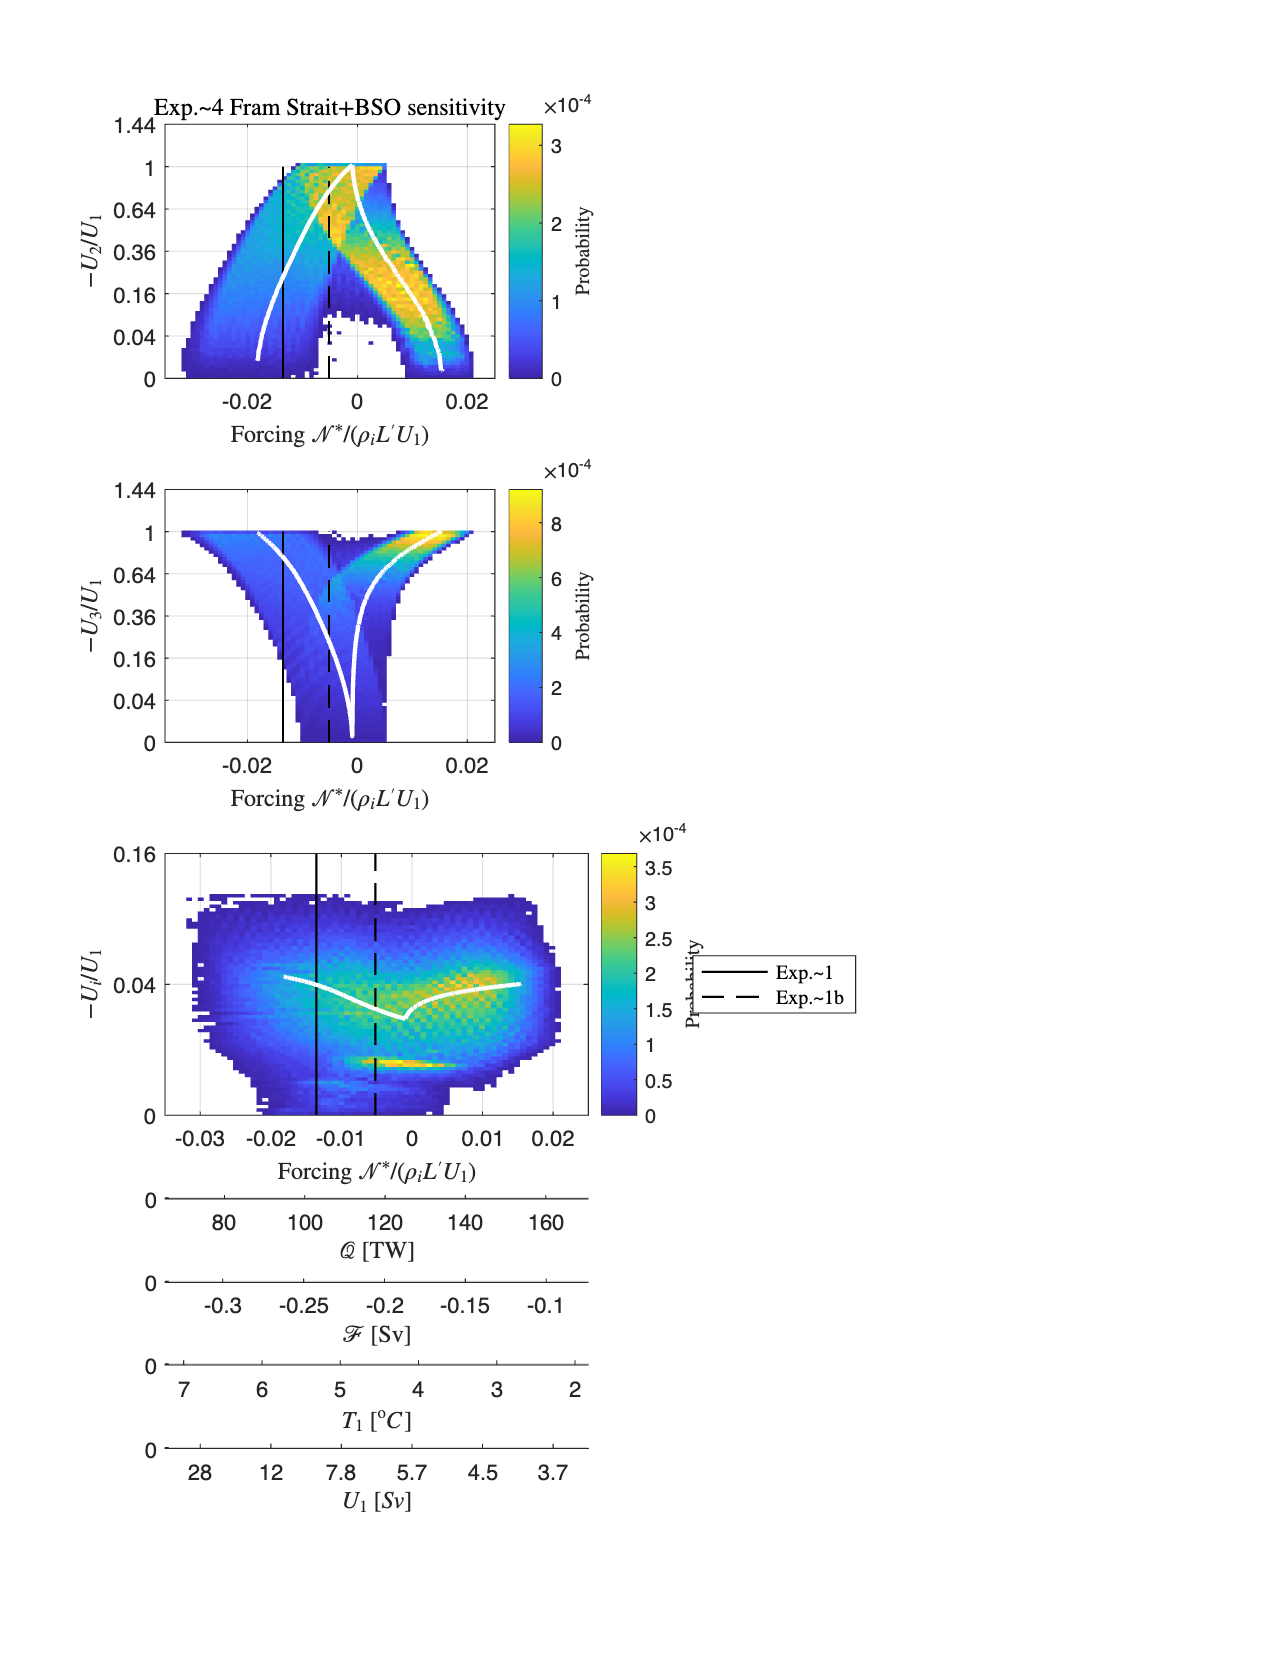

plot_POC_solutions2(model4,model3,model1,model1b)

Exp G1: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM).

return
modelG1 = build_POC_model('NH_FSBSO_LGM_can') ;
plot_POC_solution(modelG1)
modelG1 = build_stable_isotope_model(modelG1) ;

Exp G1b: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM) with warm AW.

modelG1b = build_POC_model('NH_FSBSO_LGM_hiT1') ;
plot_POC_solution(modelG1b)
modelG1b = build_stable_isotope_model(modelG1b) ;

Exp G2: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM) with lower Q

modelG2 = build_POC_model('NH_FSBSO_LGM_lowQ') ;
plot_POC_solution(modelG2)
modelG2 = build_stable_isotope_model(modelG2) ;